# EE525 Project 4

Author: Grant Gallagher

Date: 11/20/2021

Use MATLAB to implement a Kalman filter that tracks a moving target. The dataset is 2D (X,Y) measurement data of the position of a US Navy ship over a span of approximately eight minutes. Set up a Kalman filter with  a  [position_X,  velocity_X,  position_Y,  velocity_Y]  state.  The Kalman filter should function in ‘realtime’ – that is processing should occur as the measurements are read. Experiment with the filter parameters, and study their effects on tracking performance. 

Submit the following:

-  A report documenting the set up and implementation of the filter, plots  of  the  raw  measurements  and  filtered  signal,  the  problems you  encountered,  analysis  and  discussion  of  the  results.  Also include your effort in “tweaking” the filter parameters (55 points).

- Well-documented  source  code.  If  more  than  one  function/file  is  used, provide detailed description as to how to run it (25 points). 

- Repeat 1-2 for an additional dataset. It is a 3D (X,Y,Z) measurement data of the position of a US Navy submarine over a span of approximately two minutes (20 points).  

Clear Console

clc;
clear;

Import the Data

varNames = {'Time','North','East'};
varTypes = {'datetime','double','double'};
ship_data = importShipData('3Ddata.txt',varNames,varTypes)

ship_data = 514×3 table
        Time        North    East 
    ____________    _____    _____

    06:08:53.859    25198    11552
    06:08:57.360    24633    11267
    06:08:57.860    24554    11238
    06:08:58.109    24511    11220
    06:08:58.359    24452    11208
    06:08:58.611    24401    11192
    06:08:59.680    24264    11130
    06:08:59.931    24108    11059
    06:09:00.181    24082    11048
    06:09:00.431    24043    11029
    06:09:00.681    24063    11026
    06:09:00.931    24006    10999
    06:09:01.180    23903    10954
    06:09:01.430    23922    10968
    06:09:01.680    23825    10917
    06:09:01.930    23794    10906


Define State Space Matrix


$$x=x_0 +\dot{x} \Delta t+\frac{1}{2}\ddot{x} {\Delta t}^2$$



$$\left\lbrack \begin{array}{c}
x\\
\dot{x} \\
y\\
\dot{y} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
1 & \Delta t & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & \Delta t\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\dot{x} \\
y\\
\dot{y} 
\end{array}\right\rbrack$$


Initial Estimates for ${{\hat{x} }_k }^-$ and its error covariance ${P_k }^-$.

stateVarNames = {'Time','X_North','V_North','X_East','V_East'};
stateVarTypes = {'datetime','double','double','double','double'};
filtered_data = table('Size',[height(ship_data) length(stateVarNames)], ...
                      'VariableTypes',stateVarTypes, ...
                      'VariableNames',stateVarNames);

dt    = 1; % Initial sample time (sec)
x_pos = 58259; % Initial X position (m)
x_vel = 1; % Initial X velocity (m/s)
y_pos = 87660; % Initial Y position (m) 
y_vel = 1; % Initial Y velocity (m/s)

x_hat_prev = [x_pos;
              x_vel;
              y_pos;
              y_vel];
n = length(x_hat_prev); % Order of the system
P_prev = [ 100  0   0   0;
           0   1   0    0;
           0   0   100  0;
           0   0  0     1]

P_prev =    100     0     0     0
     0     1     0     0
     0     0   100     0
     0     0     0     1


Define the process and measurement covariance matrices $Q$ and $R$

H = eye(n); % Measurement Matrix
Q = eye(n)*1e-5;
R = eye(n)*0.25

R =     0.2500         0         0         0
         0    0.2500         0         0
         0         0    0.2500         0
         0         0         0    0.2500


Predicted Values

for k = 1:height(ship_data)
    %% --- Measurement Update ("Correct") ---
    % (1) Compute Kalman gain
    K = P_prev*H'*inv(H*P_prev*H'+R)';
    
    % (2) Update estimate with measurement z_k 
    % Store old ship data values
    if k > 1
        time_old = time;
    end
    x_pos_old = x_pos;
    y_pos_old = y_pos;
    
    % Read new ship data values
    [time, x_pos, y_pos] = readShipData(ship_data, k);
    
    % Calculate derivative values
    if k > 1
        dt = datenum(time-time_old)*60*60*24;
    end
    x_vel_new = (x_pos-x_pos_old)/dt;
    y_vel_new = (y_pos-y_pos_old)/dt;
    
    x = [x_pos;
         x_vel;
         y_pos;
         y_vel];
     
    z = H*x;
    
    
    x_hat = x_hat_prev+K*(z-H*x_hat_prev);
    % Store filtered data
    filtered_data(k,2:end) = array2table(x_hat');
    filtered_data.Time(k) = time;
    filtered_data.Time.Format = 'HH:mm:ss.SSS';
    
    % (3) Update the error covariance
    P = (eye(n)-K*H)*P_prev;
   
    
    %% --- Time update ("Predict") ---
    % (1) Project the state ahead
    phi = [1 dt 0  0;
           0  1 0  0;
           0  0 1 dt;
           0  0 0  1];
       
    x_hat_new = phi*x_hat;  
    
    x_hat_prev = x_hat_new;
    % (2) Project the error covariance ahead
    P_new = phi*P*phi'+Q;
    P_prev = P_new;
end

Convert Data to table outputs

filtered_data

filtered_data = 514×5 table
        Time        X_North    V_North    X_East    V_East 
    ____________    _______    _______    ______    _______

    06:08:53.859     25281           1    11742           1
    06:08:57.360     24899      -117.1    11462     -85.577
    06:08:57.860     24565     -96.738    11241     -65.559
    06:08:58.109     24524     -93.033    11221     -61.448
    06:08:58.359     24490     -93.292    11211     -59.177
    06:08:58.611     24454     -94.303    11198      -57.67
    06:08:59.680     24396      -99.74    11174     -58.714
    06:08:59.931     24247      -107.3    11101     -60.262
    06:09:00.181     24194     -111.53    11080     -60.838
    06:09:00.431     24146     -114.54    11060     -61.261
    06:09:00.681     24112     -114.82    11044     -61.033
    06:09:00.931     

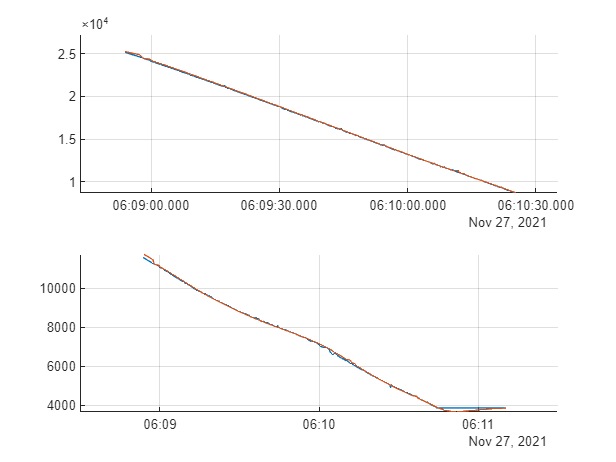

fig2 = figure(2);
subplot(2,1,1)
hold on
plot(ship_data.Time, ship_data.North)
plot(filtered_data.Time, filtered_data.X_North)
hold off
grid on

subplot(2,1,2)
hold on
plot(ship_data.Time, ship_data.East)
plot(filtered_data.Time, filtered_data.X_East)
hold off
grid on

## Import Data

function dataTable = importShipData(fileName,varNames,varTypes)
    delimiter = '\t';        % Horizontal tab delimiter
    dataStartLine = 8;       % Start on 8th line
    extraColRule = 'ignore'; % Ignore extra columns
    opts = delimitedTextImportOptions('VariableNames',varNames,...
                                    'VariableTypes',varTypes,...
                                    'Delimiter',delimiter,...
                                    'DataLines', dataStartLine,...
                                    'ExtraColumnsRule',extraColRule);
    opts = setvaropts(opts,'Time','InputFormat','HH:mm:ss.SSS'); % Set datetime format
    dataTable = readtable(fileName, opts); % Return the ship data as a table
    dataTable = rmmissing(dataTable,1); % Remove invalid data
    % dataTable.Time = datenum(dataTable.Time); % Convert datetime to serial date number
    
    % Output
    % dataTable.Time = (dataTable.Time - dataTable.Time(1)) * 60 * 60 * 24 + 1; % Convert time to seconds
end

## Read Ship Data

function [time, x_pos, y_pos] = readShipData(ship_data_raw, k)
    time = table2array(ship_data_raw(k,1));
    x_pos = table2array(ship_data_raw(k,2));
    y_pos = table2array(ship_data_raw(k,3));
end

## Van Loan Method

function [phi, Q] = vanLoan(F,G,W,dt)
    % Calculate the size of the system
    n = length(F);
    
    % Determine A and B matrices
    A = [ -F       G*W*G';
          zeros(n)     F']*dt;
    B = expm(A);
    
    % Calculate phi and Q
    phi = B(n+1:end,n+1:end)';
    Q = phi*B(1:n,n+1:end);
end